# Lista 3

## **Wstęp**

**Funkcja **`quiver(x,y,u,v,S)`**:**

rysuje wektor na płaszczyźnie o początku w (x, y) i składowych (u, v), S kontroluje skalowanie.

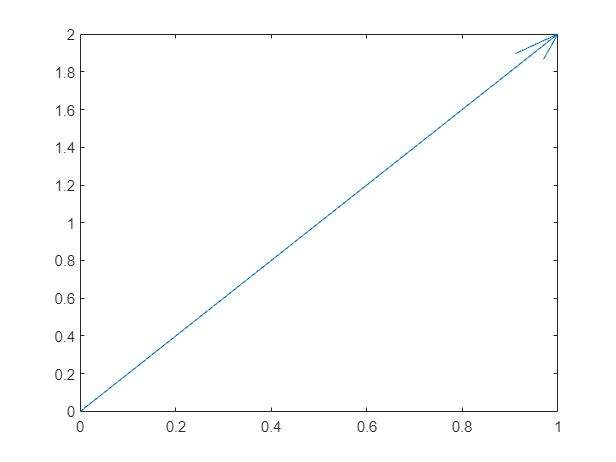

quiver(0,0, 1,2,1)

**Funkcja **`quiver3(x,y,z,u,v,w,S)`**:**

rysuje wektor 3D o początku w (x, y, z) i składowych (u, v, w), S kontroluje skalowanie.

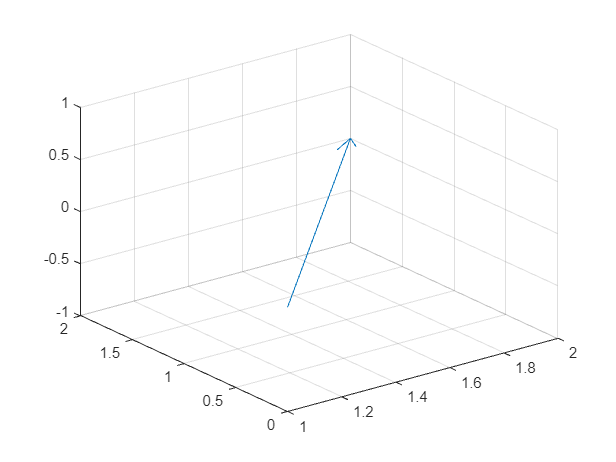

quiver3(1,0,0, 1,2,0,1)

**Instrukcja **`hold on/hold off`**:**

po wpisaniu instrukcji `hold on` kolejne elementy będą dorysowywyane, aż zostanie wpisana instrukcja `hold off`.

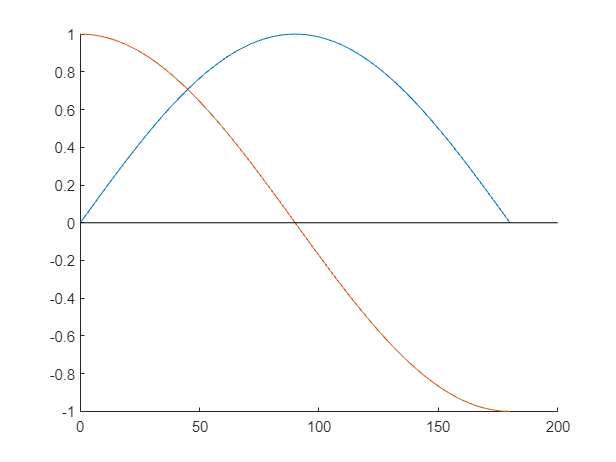

clf()                       % czyści rysunek
kat = 0:2:180;
hold on
plot(kat, sind(kat))        % wykres funkcji sin()
plot(kat, cosd(kat))        % wykres funkcji cos()
plot([0 200], [0 0], 'k')   % rysowana oś x w y=0
hold off

**Funkcja **`subplot(m,n,p)`**:**

dzieli okno rysunku na $m\times n$  podwykresów, gdzie $m$ to liczba wierszy a $n$ to liczba kolumn. Następnie wybiera *p*-ty wykres, w którym wykonywany jest rysunek.

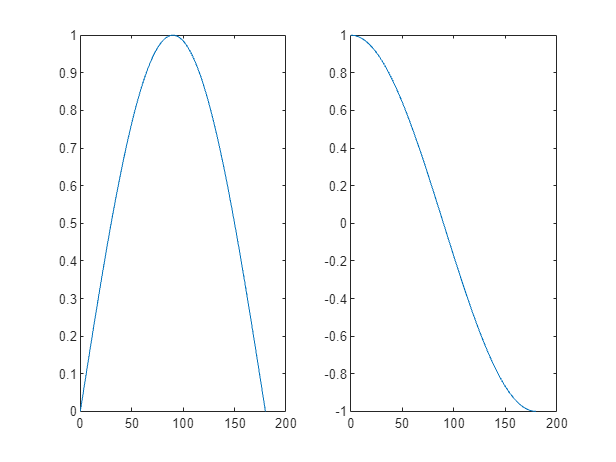

clf()
kat = 0:2:180;

% Dwa rysunki w 1 wierszu. 
% W pierwszym będzie sin()  
subplot(1,2,1) 
plot(kat, sind(kat))        % wykres funkcji sin()

% W drugim będzie cos()  
subplot(1,2,2) 
plot(kat, cosd(kat))        % wykres funkcji sin()

**Funkcja **`text(x,y,'mój napis')`**:**

wyświetla tekst *moj napis* w miejsu wykresu o współrzędnych *x* i *y*.

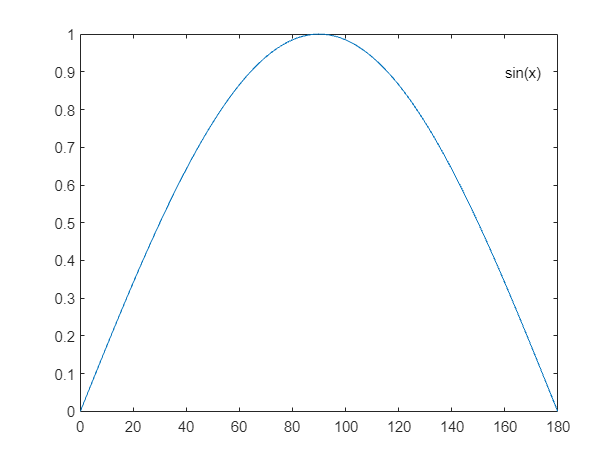

clf()
kat = 0:2:180;
plot(kat, sind(kat))        % wykres funkcji sin()
text(160,0.9,'sin(x)')

**Funkcja num2str**`(x)`**:**

zamienia liczbę rzeczywistą na tekst.

clf()
kat = 0:2:180;
plot(kat, sind(kat))        % wykres funkcji sin()
x = sind(45)

x = 0.7071

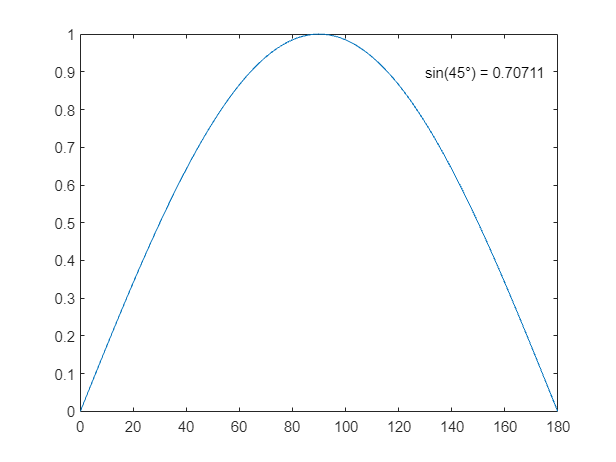

text(130,0.9,['sin(45°) = ' num2str(x)])

## **Zadania**

**Zad. 1**. Znajdź składowe $x$ i $y$ wektora przemieszczenia o 25 m pod kątem 210°. Narysuj wektor przemieszczenia i jego składowe.

clf()
W = [25*cos(deg2rad(210)), 25*sin(deg2rad(210))]

W =   -21.6506  -12.5000


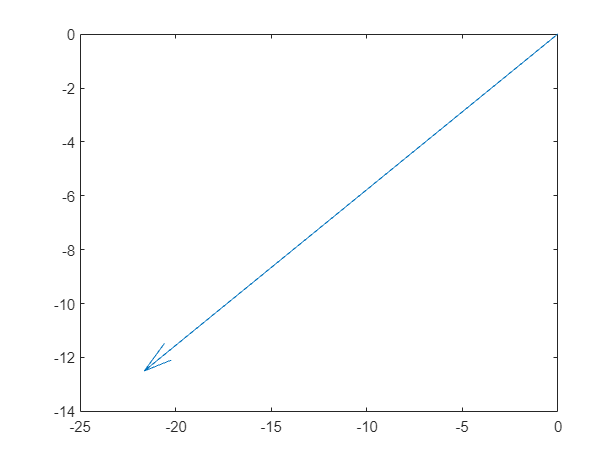

quiver(0,0, W(1),W(2),1)

**Zad. 2.** Wykorzystując składowe, znajdź całkowite przemieszczenie, jeśli pierwsze nastąpiło o 2 m pod kątem 45°, a drugie o 4 m pod kątem 127°. Na lewym wykresie umieść oba wektory opisujące przemieszczenia i wektor przedstawiający ich sumę. Na prawy wykresie umieść składowe wektorów przemieszczenia i wektor ich sumy. Końcowy rysunek powinien jak najbardziej przypominać ten załączony poniżej. Współrzędne każdego z wektorów zadania powinny być przechowywane w zmiennej typu wektor i na całych wektorach powinny być wykonywane operacje.

 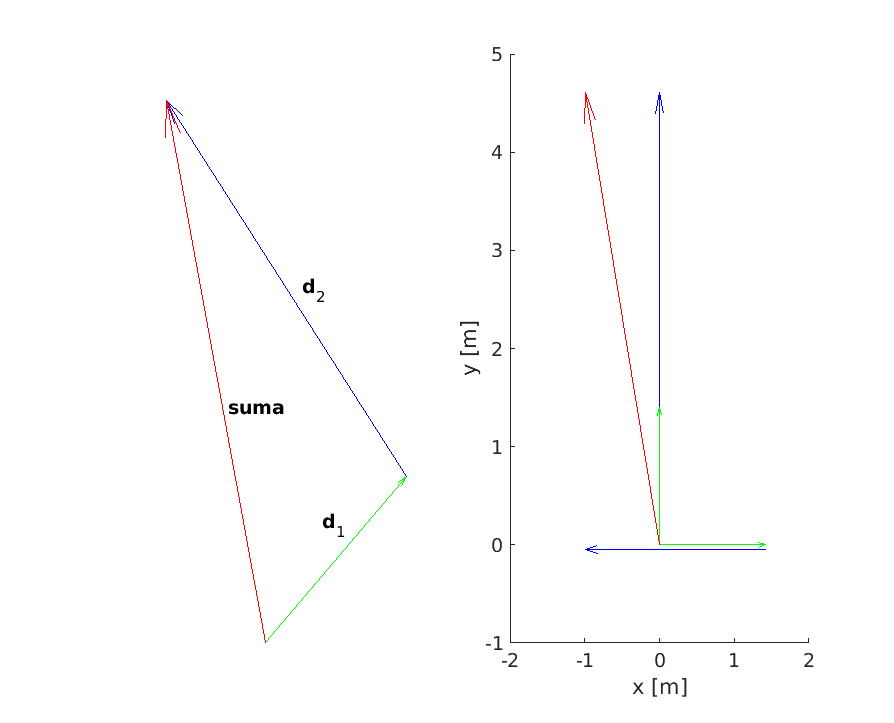

clf()
W1 = [2*cos(deg2rad(45)), 2*sin(deg2rad(45))]

W1 =     1.4142    1.4142


W2 = [4*sin(deg2rad(127)), 4*cos(deg2rad(127))]

W2 =     3.1945   -2.4073


W3 = W1+W2

W3 =     4.6088   -0.9930


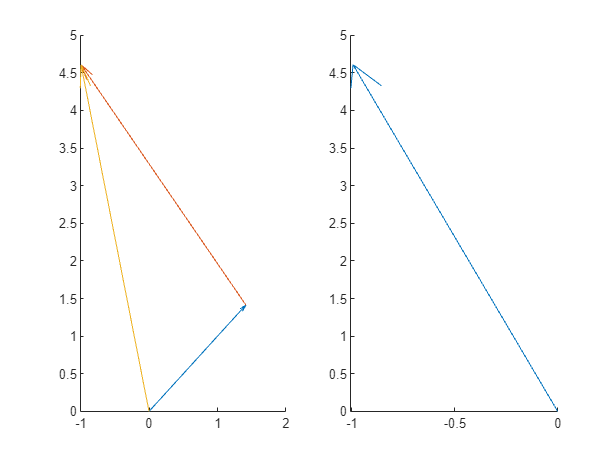


subplot(1,2,1)

hold on
quiver(0,0, W1(2),W1(1),1)
quiver(W1(2),W1(1), W2(2),W2(1),1)
quiver(0,0, W3(2),W3(1),1)
subplot(1,2,2)
hold off

hold on
quiver(0,0, W3(2),W3(1),1)

hold off

**Zad. 3.** Dla wektorów przedstawionych na rysunku znajdź $\vec{\;A} +\vec{\;B}$, $\vec{\;A} -\vec{\;B}$, $-\vec{\;A} +\vec{\;B}$, $\vec{\;A} +\vec{\;B} +\vec{\;C}$ i  $\vec{\;A} +\vec{\;B} -\vec{\;C}$. Wynik przedstaw w postaci odpowiednich wartości wektorów wyświetlonych na ekranie oraz graficznie. Podziel rysunek na odpowiednią liczbę podwykresów, aby był on czytelny. Na każdym wykresie opisz wykresy, jaka operacja jest wykonywana oraz długość wynikowego wektora.

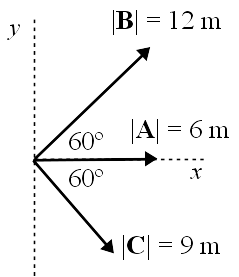

clf()
A = [6,0]

A =      6     0


B = [12*cos(deg2rad(60)), 12*sin(deg2rad(60))]

B =     6.0000   10.3923


C = [9*cos(deg2rad(-60)), 9*sin(deg2rad(-60))]

C =     4.5000   -7.7942


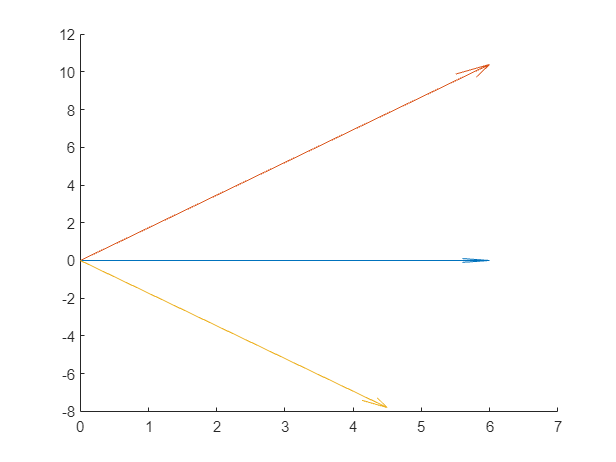


hold on
quiver(0,0,A(1),A(2),1)
quiver(0,0,B(1),B(2),1)
quiver(0,0,C(1),C(2),1)
hold off

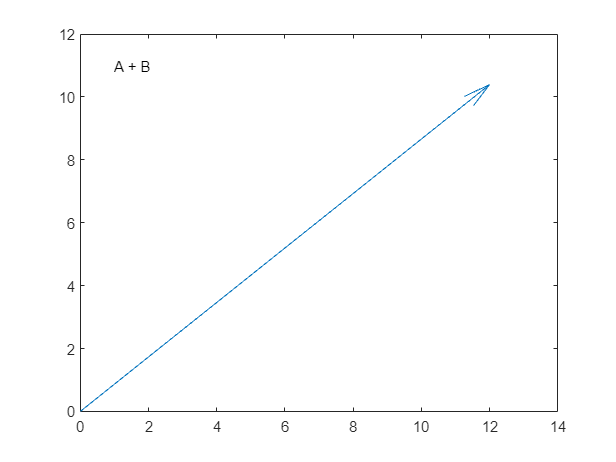



quiver(0,0,A(1)+B(1),A(2)+B(2),1)
text(1,11,['A + B'])

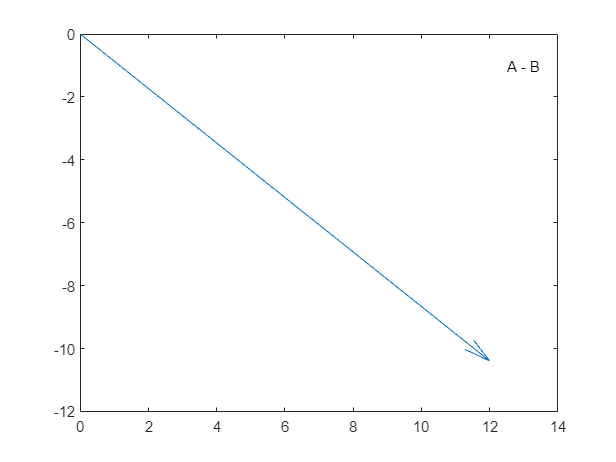


quiver(0,0,A(1)+B(1),A(2)-B(2),1)
text(12.5,-1,['A - B'])

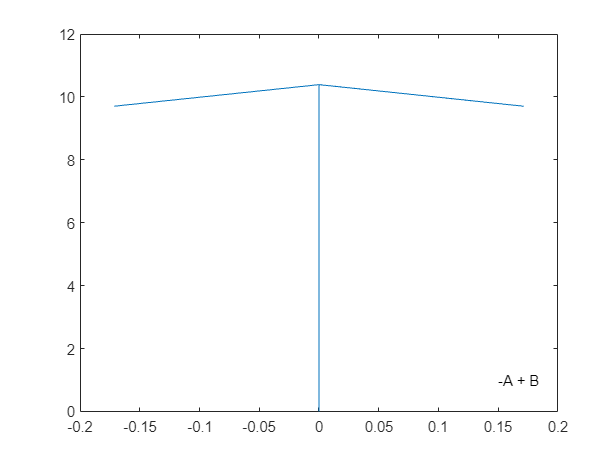


quiver(0,0,-A(1)+B(1),-A(2)+B(2),1)
text(0.15,1,['-A + B'])

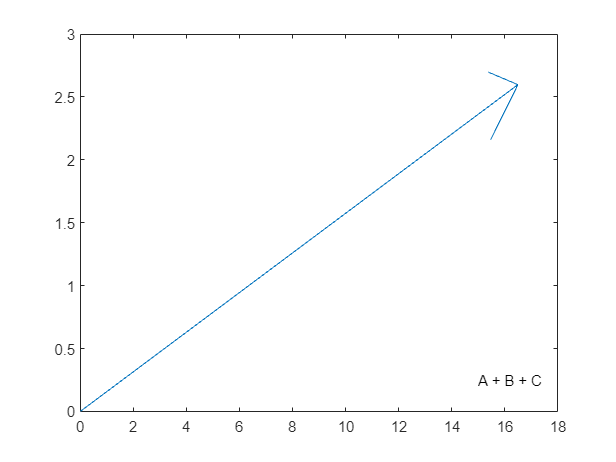


quiver(0,0,A(1)+B(1)+C(1),A(2)+B(2)+C(2),1)
text(15,0.25,['A + B + C'])

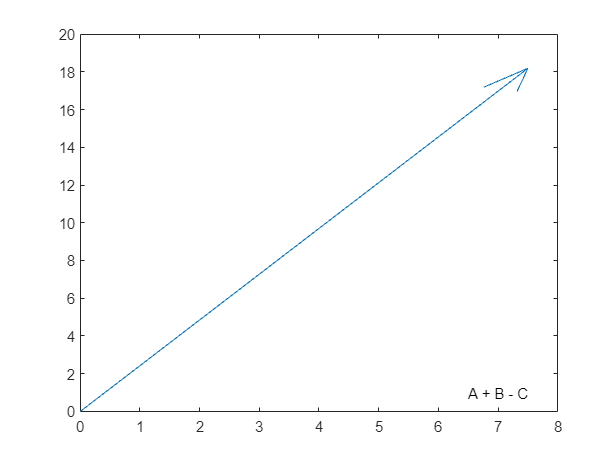


quiver(0,0,A(1)+B(1)-C(1),A(2)+B(2)-C(2),1)
text(6.5,1,['A + B - C'])